# BME3053C Project

Part II - Using established thresholding values and determined picxel counts, the stage of fibrosis was predicted on the CT scans of patients 21-50.

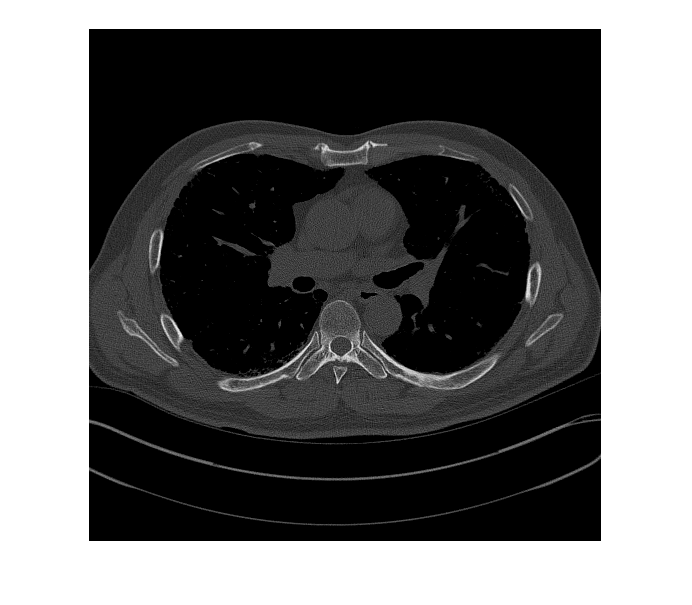

clc, clear %clear workspace
img = imread('Patient 22.png'); %read patient CTs, change the filename depending on the patient
imshow(img) %display CT image

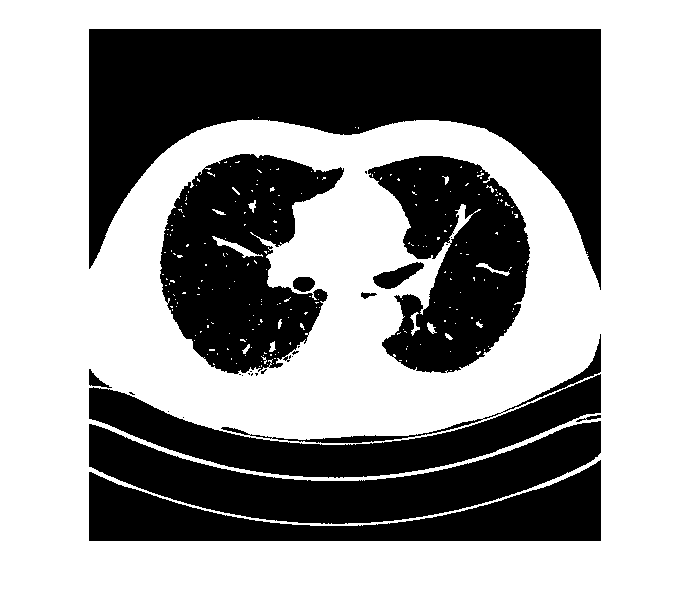

img = im2gray(img); %ensure that CT image is in grayscale
binary = img>0; %create a binary that includes every pixel from the original CT that is greater than 0
imshow(binary) %display binary image 

WhiteCount = 0; %variable that will keep track of pixels with a value of "1" in the binary image
[a, b] = size(binary); %dimesions of the image are  defined as 'a' and 'b'
for ii = 1:a %Lines 9-10 every pixel in the binary image is indexed
    for jj = 1:b
        if binary(ii,jj) == 1 %If the indexed pixel on the binary image is equal to 1, the counter increases by 1
            WhiteCount = WhiteCount+1;
        end
    end
end

if WhiteCount < 111000 %Lines 17-23 the predicted stage of fibrosis is classified based on the value of the WhiteCount pixel counter
    FibrosisStage = 'Moderate'
elseif WhiteCount < 120000
    FibrosisStage = 'Severe'
elseif WhiteCount >= 120000
    FibrosisStage = 'Very Severe'
end

FibrosisStage = 'Moderate'